%% #4 Chapra 22.19  Groundwater nonlinear 2nd-order ODE shooting method
%use shooting method and residual function to obtain dz/dx such that
%h(1000)=5 m
%kHdh/dx = z 

tspan=0:0.1:1000;
%guess initial slope = za = 0.1

%use fzero and res function with ode45
za = fzero( @res22_19, 0.1 )

za = 0.0013

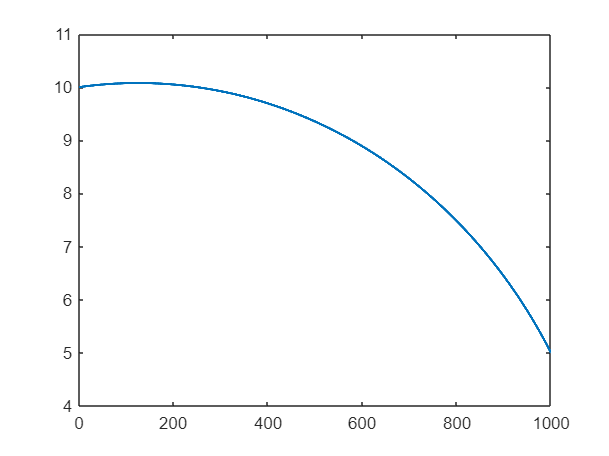


[x, h] = ode45( @grndwtr, tspan, [ 10  za ] );

%% Output
plot(x,h(:,1),'linewidth',1.6);


%Report hshoot200, hshoot700
k200=find(abs(x-200)<1e-2);
hshoot200=h(k200,1)

hshoot200 = 10.0499

k700=  find(abs(x-700)<1e-2)             ;
hshoot700=   h(k700,1)    

hshoot700 = 8.2765


%% functions

function dh = grndwtr( x,h )
%Chapra 22.19 groundwater aquifer problem
%let z=K*h*dh/dx
N=0.0001; K=1.0;
dh=[      h(2)   ;  -1*( N + K* (h(2)^2) ) /(K*h(1))                ]; %the 2 nonlinear ODEs
end

function r=res22_19(za)
%Chapra problem 22.19 nonlin ODE 
[x,h]= ode45(@grndwtr, [  0 1000     ], [  10   za    ]);
r=    h( length(x), 1 ) - 5               ;
end